#  Get Started with WLAN System-Level Simulation in MATLAB

This example shows how to model a WLAN network consisting of an IEEE® 802.11ax™ [1] access point (AP) and a station (STA) by using WLAN Toolbox™.

Using this example, you can:

- Simulate a multinode WLAN system by configuring the application layer (APP), medium access control (MAC), and physical layer (PHY) parameters at each node.

- Model uplink and downlink communication between an AP and an STA.

- Switch between the abstracted and full model of the MAC and PHY.

- Visualize the time spent by each node in idle, contention, transmission, and reception states.

- View performance metrics such as throughput, latency, packet loss, and other network-related metrics by using the `statistics.mat` file.

## WLAN System-Level Simulation

This example shows you how to model a WLAN network with uplink and downlink communication between an AP (Node 1) and an STA (Node 2). This example assumes that the AP and the STA are preassociated. Preassociation implies that the AP and the STA are connected before the start of the simulation.

This figure shows the communication between an AP and an STA.

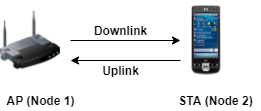

This figure shows the example workflow.

This example verifies the simulation performance against the results of Box-3 and Box-5 scenarios specified in the TGax evaluation methodology [2]. To confirm compliance with the IEEE 802.11 standard, this example validates the network throughput that is calculated for the TGax simulation scenarios [3] against the published calibration results from the TGax Task Group.

## Configure Simulation Parameters

Specify the simulation time (in milliseconds) by using the `simulationTime` variable. To visualize a live state transition plot for all of the nodes, set the `showLiveStateTransitionPlot` variable to `true`. To visualize the table containing network statistics at the end of simulation, set the `displayStatistics` variable to `true`.

Set the seed for the random number generator to 1. The seed value controls the pattern of random number generation. The random number generated by the seed value impacts the backoff counter selection at the MAC and path-loss modeling at the PHY. For high fidelity simulation results, change the seed value and average the results over multiple simulations.

rng(1,'combRecursive');             % Seed for random number generator
simulationTime = 1000;              % Simulation time in milliseconds
showLiveStateTransitionPlot = true; % Enable live state transition plot for all nodes
displayStatistics = true;           % Display statistics at the end of the simulation

% To access all of the helper files in this example, add the
% mlWLANSystemSimulation folder to the MATLAB path
addpath(genpath(fullfile(pwd,'mlWLANSystemSimulation')));

### Nodes

Configure the WLAN nodes by using these parameters.

- `numNodes` - Specifies the desired number of nodes in the network

- `nodePositions` - Specifies the position of nodes in `x`-, `y`-, and `z`- Cartesian coordinate system

- `nodeConfig` - Specifies the MAC and PHY configuration of each node

Specify the number of nodes in the network by changing the values of the `numNodes`, `nodePositions`, `nodeConfig`, and `trafficConfig` parameters.

numNodes = 2;

Specify the positions of WLAN nodes as a `numNodes`-by-3 matrix, where `numNodes` is the number of nodes in the network. Each row specifies the Cartesian coordinates of a node, starting from the first node.

nodePositions = [10 0 0; 20 0 0]; % In meters

Specify the configuration for each WLAN node as a `numNodes`-by-1 vector. The configuration for a node is a `wlanNodeConfig `structure.

The `wlanNodeConfig.mat` file specifies the MAC, PHY, and channel configuration structure of a node. Configuring the nodes include setting up the default node configuration and then configuring the parameters at the PHY and MAC of each node. At each node, you can configure `TxFormat`, `Bandwidth`, `BandAndChannel`, `MPDUAggregation`, and other such parameters in the `nodeConfig `structure. For more information about the configuration parameters in the MAC, PHY, and channel, see [WLAN Node Composition and Configuration](docid:wlan_ug#mw_b9335f02-2b22-48e5-9620-024a305d6ade).

% Default configuration for all of the nodes
load('wlanNodeConfig.mat');
nodeConfig = repmat(wlanNodeConfig,1,numNodes);

% Configure the AP
nodeConfig(1).NodePosition = nodePositions(1,:);
nodeConfig(1).TxFormat = 'HE_SU';
nodeConfig(1).BandAndChannel = {[5 36]};
nodeConfig(1).Bandwidth = 20;                    % MHz
nodeConfig(1).MPDUAggregation = true;
nodeConfig(1).TxMCS = 2;
nodeConfig(1).NumTxChains = 1;
nodeConfig(1).DisableRTS = false; 
nodeConfig(1).DisableAck = false;

% Configure the STA
nodeConfig(2).NodePosition = nodePositions(2,:);
nodeConfig(2).TxFormat = 'HE_SU';
nodeConfig(2).BandAndChannel = {[5 36]};
nodeConfig(2).Bandwidth = 20;                    % MHz
nodeConfig(2).MPDUAggregation = true;
nodeConfig(2).TxMCS = 2;
nodeConfig(2).NumTxChains = 1;
nodeConfig(2).DisableRTS = false; 
nodeConfig(2).DisableAck = false;

### Application Traffic

The `wlanTrafficConfig.mat `file specifies the structure to configure the application at a node. To model downlink traffic at an AP to an STA, set the `SourceNode` and `DestinationNode` values in the `trafficConfig` structure with the AP and STA node numbers, respectively. To model uplink traffic at an AP from an STA, set the `SourceNode` and `DestinationNode` values in the `trafficConfig` structure with the STA and the AP node numbers, respectively.

To configure multiple applications, follow these steps.

- Copy the default configuration to each element of the `trafficConfig` structure vector.

- Update the traffic configuration for the new elements.

For more information about the configuration parameters, see [WLAN Node Composition and Configuration](docid:wlan_ug#mw_b9335f02-2b22-48e5-9620-024a305d6ade).

% Load the application traffic configuration for WLAN nodes
load('wlanTrafficConfig.mat');

% Copy the default configuration for all of the nodes
trafficConfig = repmat(wlanTrafficConfig,1,numNodes);

% Configure downlink application traffic
trafficConfig(1).SourceNode = 1;        % AP node ID
trafficConfig(1).DestinationNode = 2;   % STA node ID
trafficConfig(1).DataRateKbps = 100000;
trafficConfig(1).PacketSize = 1500;     % In bytes
trafficConfig(1).AccessCategory = 0;    % Best Effort (0), Background (1), Video (2), and Voice (3)

% Configure uplink application traffic
trafficConfig(2).SourceNode = 2;        % STA node ID
trafficConfig(2).DestinationNode = 1;   % AP node ID
trafficConfig(2).DataRateKbps = 100000;
trafficConfig(2).PacketSize = 1500;     % In bytes
trafficConfig(2).AccessCategory = 0;    % Best Effort (0), Background (1), Video (2), and Voice (3)

## Create WLAN Scenario

The `hCreateWLANNodes` helper function enables you to: 

- Create WLAN nodes with the APP, MAC, and PHY layers configured with the preceding parameters.

- Add custom algorithms at the APP, MAC, and PHY layers by modifying the algorithm configuration code in the `hCreateWLANNodes` helper function.

By default, the `hCreateWLANNodes` helper function configures abstracted MAC and PHY at each WLAN node.

At the transmitter and receiver, modeling full MAC processing involves complete MAC frame generation at the MAC layer. Similarly, modeling full PHY processing involves complete operations related to waveform transmission and reception through a fading channel. When simulating large networks, full MAC and PHY processing is computationally expensive.

In the abstracted MAC, the node does not generate or decode any frames at the MAC layer. Similarly, in the abstracted PHY, the node does not generate or decode any waveforms at the PHY. MAC and PHY abstraction enables you to minimize the complexity and duration of system-level simulations. For more information on PHY abstraction, see the [Physical Layer Abstraction for System-Level Simulation](docid:wlan_ug#example-PHYAbstractionExample) example.

The `hCreateWLANNodes` helper function enables you to switch between the abstracted and full model of the MAC or PHY by configuring the `MACFrameAbstraction` and `PHYAbstractionType` input parameters. The valid values for these parameters are:

- `MACFrameAbstraction` `-` true or false

- `PHYAbstractionType` - ‘TGax Evaluation Methodology Appendix 1’ (default), ‘TGax Simulation Scenarios MAC Calibration’, or ‘None’

If you set the `PHYAbstractionType` to `'TGax Evaluation Methodology Appendix 1'`, the PHY estimates the performance of a link with the TGax channel model by using an effective signal-to-interference-plus-noise ratio (SINR) mapping. Alternatively, if you set the `PHYAbstractionType` to `'TGax Simulation Scenarios MAC Calibration'` the PHY assumes a packet failure on interference without actually calculating the link performance. To use the full PHY, set the value of `PHYAbstractionType` to `'None'`.

MACFrameAbstraction = true;
PHYAbstractionType  = "TGax Evaluation Methodology Appendix 1";

wlanNodes = hCreateWLANNodes(nodeConfig,trafficConfig,...
'MACFrameAbstraction',MACFrameAbstraction,...
'PHYAbstractionType',PHYAbstractionType);

This table shows how to switch between the abstracted and full MAC or PHY by configuring the values of the `MACFrameAbstraction` and `PHYAbstractionType` input parameters.

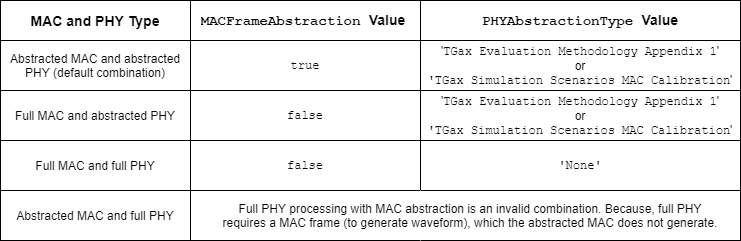

## Simulation

To initialize the visualization parameters and simulate the WLAN scenario, use the `hStatsLogger` and `hWirelessNetworkSimulator` helper functions, respectively.

% Initialize the visualization parameters
visualizationInfo = struct;
visualizationInfo.Nodes = wlanNodes;
visualizationInfo.NodeNames = {'AP','STA'};
statsLogger = hStatsLogger(visualizationInfo);

% Configure state transition visualization
if showLiveStateTransitionPlot
    hPlotStateTransition(visualizationInfo);
end


% Initialize the wireless network simulator
networkSimulator = hWirelessNetworkSimulator(wlanNodes);

The network simulator provides the flexibility to schedule custom events in the simulation by using the `scheduleEvent` object function.

For example, every time when you call the simulator, you can schedule an event to refresh the state transition visualization. When you run the example from MATLAB command prompt, this event pause the execution to refresh visualization after every 5 milliseconds.

To schedule an event, specify the function handle, input arguments, time to call the event, and periodicity of the event.

scheduleEvent(networkSimulator,@() pause(0.001),[],0,5);

For more information on scheduling events, enter this command at the MATLAB command prompt.

`help hWirelessNetworkSimulator.scheduleEvent`

Run all of the nodes in the network for the specified simulation time, and visualize the state transition periods of the nodes.

run(networkSimulator,simulationTime);

Clean up the persistent variables used in functions.

clear hPlotStateTransition;

## Results

At each node, the simulation captures these network statistics.

- MAC throughput

- The time spent in the contend state, idle state, and sending data state

- Tx and Rx statistics at the APP, MAC and PHY

Retrieve the statistics and save them in a MAT-file.

statistics = getStatistics(statsLogger,displayStatistics);
save('statistics.mat','statistics');

You can access all of the statistics from the preceding table by using the `statistics.mat` file. For more information about the statistics captured at each node, see [Statistics Captured in WLAN System-Level Simulation](docid:wlan_ug#mw_2d508526-d8b1-4283-a4e8-7a83c4496faf).

The `hPlotNetworkStats` helper function parses the collected statistics and plots the throughput, packet-loss ratio, and average packet latency at each node. This plot shows the throughput (in Mbps) and packet-loss ratio (ratio of unsuccessful data transmissions to the total data transmissions) at the AP and the STA. The plot also shows the average packet latency experienced at the STA. The average packet latency shows the average latency that the STA incurs to receive the downlink traffic from the AP.

hPlotNetworkStats(statistics,wlanNodes);

At the end of simulation, remove the mlWLANSystemSimulation folder from the path.

rmpath(genpath(fullfile(pwd,'mlWLANSystemSimulation')));

## References

- IEEE P802.11ax™/D4.1. "Amendment 6: Enhancements for High Efficiency WLAN." Draft Standard for Information technology - Telecommunications and information exchange between systems Local and metropolitan area networks - Specific requirements -Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications.

- “TGax simulation scenarios”, doc. IEEE 802.11-14/0980r16.

- “11ax evaluation methodology”, doc. IEEE 802.11-14/0571r12.

*Copyright 2021 The MathWorks, Inc.*